# TP 4 - Transformée en distance 

## I. Modelling 

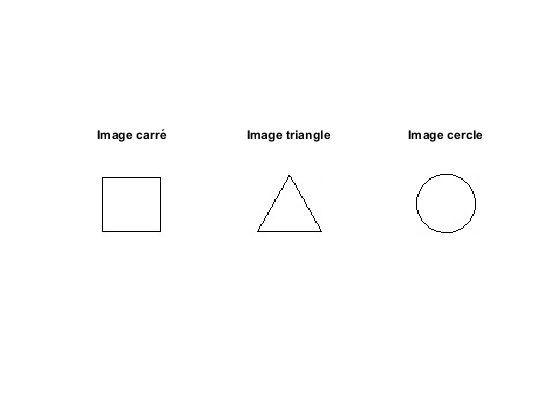

img_carre=imread('carre.jpg');
img_triangle=imread('triangle.jpg');
img_cercle=imread('cercle.jpg');
figure(1);
subplot(1,3,1)
imshow(img_carre);
title("Image carré")
subplot(1,3,2)
imshow(img_triangle);
title("Image triangle")
subplot(1,3,3)
imshow(img_cercle);
title("Image cercle")

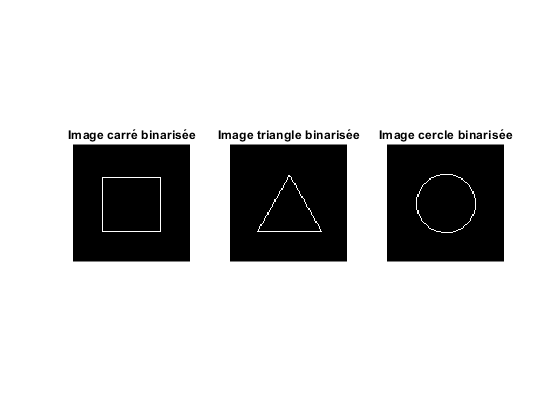



img_carre_bin=binarisation(img_carre);
img_triangle_bin=binarisation(img_triangle);
img_cercle_bin=binarisation(img_cercle);

figure(2);
subplot(1,3,1)
imshow(img_carre_bin);
title("Image carré binarisée")
subplot(1,3,2)
imshow(img_triangle_bin);
title("Image triangle binarisée")
subplot(1,3,3)
imshow(img_cercle_bin);
title("Image cercle binarisée")

chanfrein=[4 3 4;1 0 1;4 3 4]

chanfrein =      4     3     4
     1     0     1
     4     3     4


img_carre_transform=distance_transform(img_carre_bin,chanfrein);
img_triangle_transform=distance_transform(img_triangle_bin,chanfrein);
img_cercle_transform=distance_transform(img_cercle_bin,chanfrein);

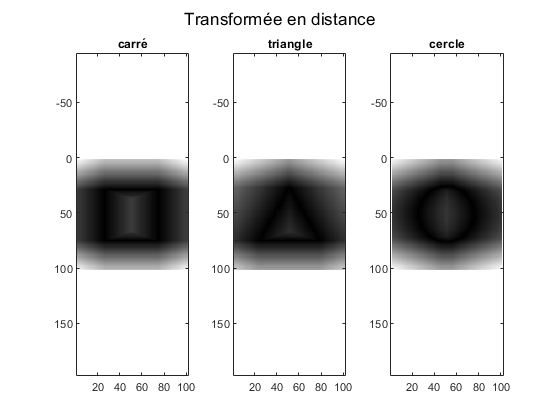

figure(3)
colormap(gray(256));
subplot(1,3,1)
imagesc(img_carre_transform)
title("carré")
axis equal;
subplot(1,3,2)
imagesc(img_triangle_transform)
title("triangle")
axis equal;
subplot(1,3,3)
imagesc(img_cercle_transform)
title("cercle")
axis equal;

sgtitle("Transformée en distance") 

## II. Reconnaissance 

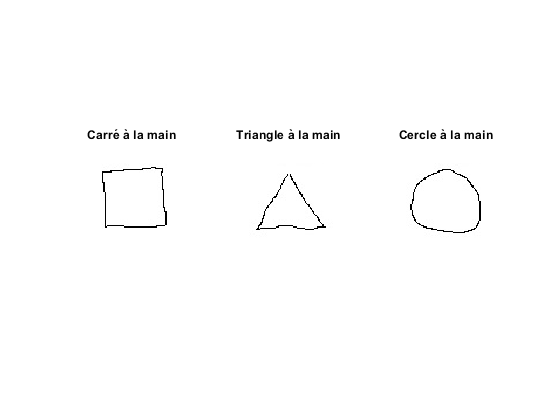

img_hcarre=imread('carre_hand.jpg');
img_htriangle=imread('triangle_hand.jpg');
img_hcercle=imread('cercle_hand.jpg');
figure(4);
subplot(1,3,1)
imshow(img_hcarre);
title("Carré à la main")
subplot(1,3,2)
imshow(img_htriangle);
title("Triangle à la main")
subplot(1,3,3)
imshow(img_hcercle);
title("Cercle à la main")

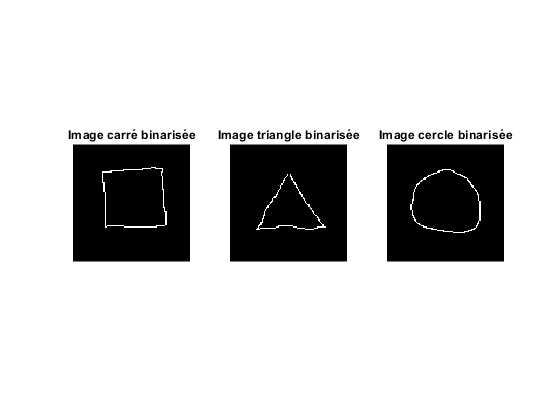

img_hcarre_bin=binarisation(img_hcarre);
img_htriangle_bin=binarisation(img_htriangle);
img_hcercle_bin=binarisation(img_hcercle);

figure(5);
subplot(1,3,1)
imshow(img_hcarre_bin);
title("Image carré binarisée")
subplot(1,3,2)
imshow(img_htriangle_bin);
title("Image triangle binarisée")
subplot(1,3,3)
imshow(img_hcercle_bin);
title("Image cercle binarisée")

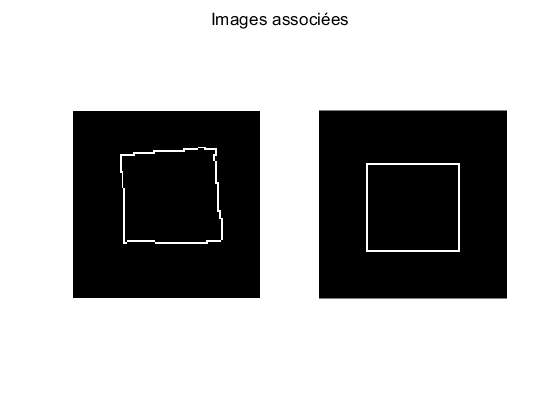

img_carre_transform=img_carre_transform(2:101,2:101);
img_triangle_transform=img_triangle_transform(2:101,2:101);
img_cercle_transform=img_cercle_transform(2:101,2:101);

res1=img_carre_transform .* img_hcarre_bin;
res2=img_triangle_transform .* img_hcarre_bin;
res3=img_cercle_transform .* img_hcarre_bin;
sum1 = sum(sum(res1));
sum2 = sum(sum(res2));
sum3 = sum(sum(res3));
listsame=[sum1 sum2 sum3];
[minimum,ind]=min(listsame);
if(ind==1)
    figure(6)
    subplot(1,2,1)
    imshow(img_hcarre_bin);
    subplot(1,2,2)
    imshow(img_carre_bin);
    sgtitle("Images associées") 
    elseif(ind==2)
    figure(6)
    subplot(1,2,1)
    imshow(img_hcarre_bin);
    subplot(1,2,2)
    imshow(img_triangle_bin);
    sgtitle("Images associées") 
        
    elseif(ind==3)
    figure(6)
    subplot(1,2,1)
    imshow(img_hcarre_bin);
    subplot(1,2,2)
    imshow(img_cercle_bin);
    sgtitle("Images associées")   
end

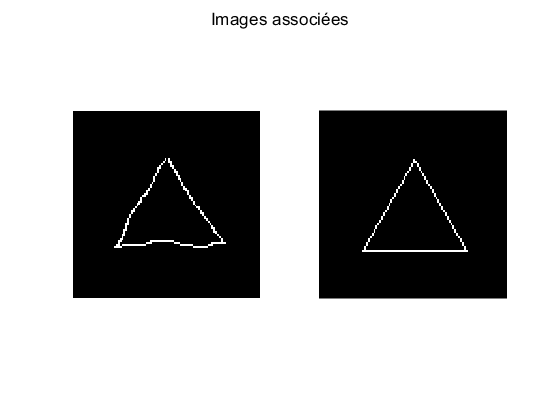

res1=img_carre_transform .* img_htriangle_bin;
res2=img_triangle_transform .* img_htriangle_bin;
res3=img_cercle_transform .* img_htriangle_bin;
sum1 = sum(sum(res1));
sum2 = sum(sum(res2));
sum3 = sum(sum(res3));
listsame=[sum1 sum2 sum3];
[minimum,ind]=min(listsame);
if(ind==1)
    figure(7)
    subplot(1,2,1)
    imshow(img_htriangle_bin);
    subplot(1,2,2)
    imshow(img_carre_bin);
    sgtitle("Images associées") 
    elseif(ind==2)
    figure(7)
    subplot(1,2,1)
    imshow(img_htriangle_bin);
    subplot(1,2,2)
    imshow(img_triangle_bin);
    sgtitle("Images associées") 
        
    elseif(ind==3)
    figure(7)
    subplot(1,2,1)
    imshow(img_htriangle_bin);
    subplot(1,2,2)
    imshow(img_cercle_bin);
    sgtitle("Images associées")   
end

res1=img_carre_transform .* img_hcercle_bin;
res2=img_triangle_transform .* img_hcercle_bin;
res3=img_cercle_transform .* img_hcercle_bin;
sum1 = sum(sum(res1));
sum2 = sum(sum(res2));
sum3 = sum(sum(res3));
listsame=[sum1 sum2 sum3]

listsame =          942        2103        1052


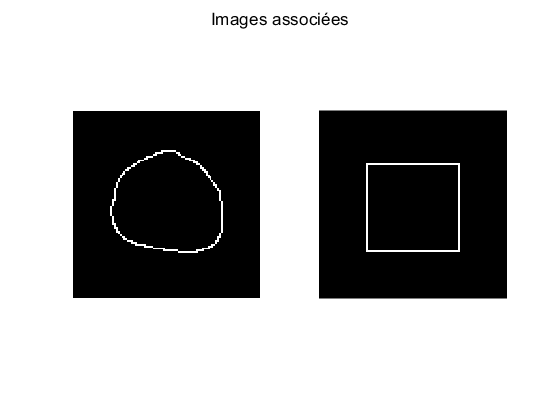

[minimum,ind]=min(listsame);
if(ind==1)
    figure(8)
    subplot(1,2,1)
    imshow(img_hcercle_bin);
    subplot(1,2,2)
    imshow(img_carre_bin);
    sgtitle("Images associées") 
    elseif(ind==2)
    figure(8)
    subplot(1,2,1)
    imshow(img_hcercle_bin);
    subplot(1,2,2)
    imshow(img_triangle_bin);
    sgtitle("Images associées") 
        
    elseif(ind==3)
    figure(8)
    subplot(1,2,1)
    imshow(img_hcercle_bin);
    subplot(1,2,2)
    imshow(img_cercle_bin);
    sgtitle("Images associées")   
end